# Diffusion Scaling Law: A Coordinate-Free Approach for Directed Interactions and Flows

© 2026 Moo K. Chung & Paul M. Thompson

## Diffusion Dimension for Directed Interactions

Recent scaling-law theory links sample complexity and discoverability to intrinsic dimension and spectral decay in biomedical and representation-learning data (Thompson, 2025, 2026). These studies motivate the need to quantify low-dimensional structure in complex brain network interactions. However, existing scaling approaches are not designed for directed interactions (or edge flows on network). We introduce the concept of diffusion dimension for directed network interactions using the 1-Hodge Laplacian.

Fractal dimension (FD) is a classical measure of intrinsic data complexity. In Euclidean space, FD is commonly estimated from geometric scaling laws such as box counting. For non-Euclidean data, including networks and manifolds, geometric scaling is substantially harder because sampling irregularity, heterogeneous connectivity, and the lack of a common coordinate system make covering arguments unstable. We address this limitation using diffusion-based scaling (Barlow, 2006). Rather than measuring scale by Euclidean distance, we use diffusion time generated by the 1-Hodge Laplacian as an intrinsic scale for directed edge flows. Short diffusion times probe localized high-frequency edge-flow variation, whereas longer diffusion times reveal coarse global interaction structure. The attenuation rate across diffusion scales therefore provides an effective measure of directed interaction complexity, allowing diffusion dimension to be estimated from Hodge diffusion rather than Euclidean covering numbers.

## Background

We utilize the differential geometric connection. Let $\Delta$ be the Laplace-Beltrami operator on a compact smooth $d$-dimensional Riemannian manifold $\mathcal{M}$. The heat trace is obtained by integrating the diagonal of the heat kernel $K_t$:

$Z(t)=\int_M K_t(x,x)\,dx = \mathrm{tr}\left(e^{-t\Delta}\right)$,

which measures the total amount of heat returning to its starting location after time $t$, aggregated over the entire space. This intrinsic diffusion behavior can be used to measure the dimension of the underlying space because heat dissipates at a rate determined by how many independent directions are available for diffusion. The heat trace has the asymptotic expansion


$$Z(t) = (4\pi t)^{-d/2}\sum_{n=0}^{\infty} a_n t^n$$


as $t \to 0$ for some coefficients $a_n$ depend on the geometry of the manifold (Rosenberg, 1997). The first term $a_0 = vol (\mathcal{M})$ dominates the expansion. Thus, we have

$Z(t) = (4\pi t)^{-d/2} [a_0+ \mathcal{O}(t)]$.

Thus we have power law $Z(t) \propto t^{-d/2}$ ignoring the multiplicative constant, which affects only the intercept in the log-log plot. Heat-trace scaling provides a diffusion-based analogue of geometric dimension. 

## Heat Trace for 1-Hodge Laplacian

Let $\Delta_1 = B_1^\top B_1 + B_2 B_2^\top$ denote the 1-Hodge Laplacian of underlying network, where $B_1$ and $B_2$ are the vertex-edge and edge-face incidence (boundary) matrices (Anand & Chung, 2023). Consider eigensystem $\Delta_1\phi_k=\lambda_k\phi_k$, where $\lambda_k$ is the $k$-th Hodge eigenvalue and $\phi_k$ is the corresponding eigenvector. Given an edge weight vector $X(0) \in \mathbb{R}^{|E|}$, we have Hodge diffusion


$$X(t)= e^{-t\Delta_1}X(0),$$
 

which spectrally diffuse edge interactions across neighboring edges and higher-order cycles (Chung et al. 2026). The solution is analytically given as


$$X(t)=\sum_{k=1}^{|E|} e^{-t\lambda_k}\langle X,\phi_k\rangle \phi_k.$$


Diffusion scaling is characterized through the heat trace, which summarizes the spectral density of the 1-Hodge Laplacian across all spectrums:


$$Z(t)=\mathrm{tr}(e^{-t\Delta_1}) =\sum_{k=1}^{|E|} e^{-t\lambda_k},$$


where $\lambda_k$ is a diffusion frequency. Diffusion converges to a harmonic steady state. If the directed interactions contain persistent cyclic structure, the limiting flow lies in the harmonic subspace $\ker(\Delta_1)$ (Chung et al. 2026), whose dimension is the first Betti number $\beta_1$, i.e., $\beta_1=\dim\ker(\Delta_1)$.

Then the heat trace decomposes as


$$Z(t)= \beta_1+\sum_{\lambda_k>0}e^{-t\lambda_k}.$$


The term $\beta_1$ is the non-decaying harmonic component that counts persistent cyclic modes, while the positive-eigenvalue terms represent transient non-harmonic modes that decay exponentially under diffusion. We therefore define diffusion scaling on the decaying heat trace after removing the persistent cyclic baseline:


$$Z(t)-\beta_1 \approx C t^{-d_H/2}$$


where $d_H$ denotes the diffusion dimension of flow interactions. Classical FD measures how spatial detail grows as geometric resolution increases; $d_H$ measures how many transient interaction modes remain active as diffusion scale changes. Thus, $d_H$ is a Hodge diffusion analogue of FD, characterizing the multiscale complexity of directed interactions after removing the persistent cyclic component $\beta_1$.

***    Imlementation Issue. ***For finite networks, the small-time regime is not informative because $Z(t)$ approaches the total number of edges as $t \to 0$. Thus, we have $\beta_1 \leq Z(t)  \leq |E|$ and $Z(t)$ looks like a left-right flipped S-shape.  We therefore estimate $d_H$ over an intermediate diffusion range, such as $t \in [0.1,10]$, where the decaying heat trace $Z(t)-\beta_1$ exhibits approximately linear behavior on the log-log scale. 

## Example: Directed Sierpinski Gasket

We illustrate the proposed diffusion scaling on a directed Sierpinski gasket. Unlike the traditional undirected gasket used in box-counting analysis, we assign an orientation to each edge and treat the resulting object as a directed simplicial complex. The goal is not to recover the classical box-counting dimension from Euclidean coverings, but to quantify how directed edge-flow interactions diffuse across the multiscale topology of the gasket. Note that the FD of Sierpinnski gasket is $\frac{\log 3}{\log 2} = 1.585$, at level 5, we are estimating it as $d_H = 1.51$.

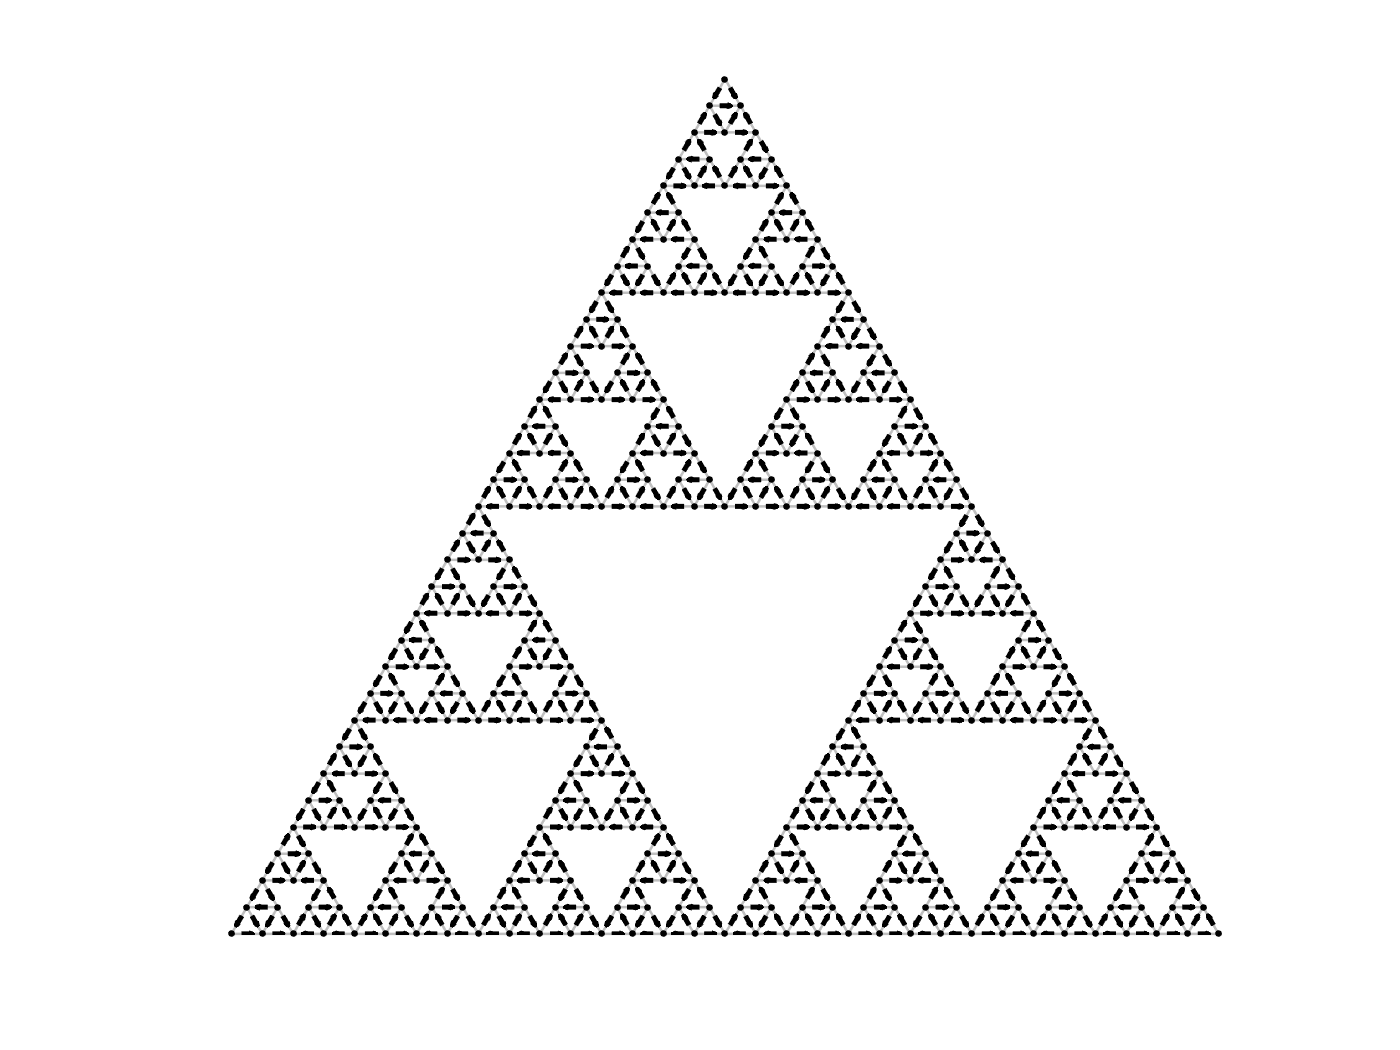

%% Sierpinski complex with random edge orientations

S = complex_sierpinski_random(5); % level 5-7 give resonable estimate. 
complex_display(S); 

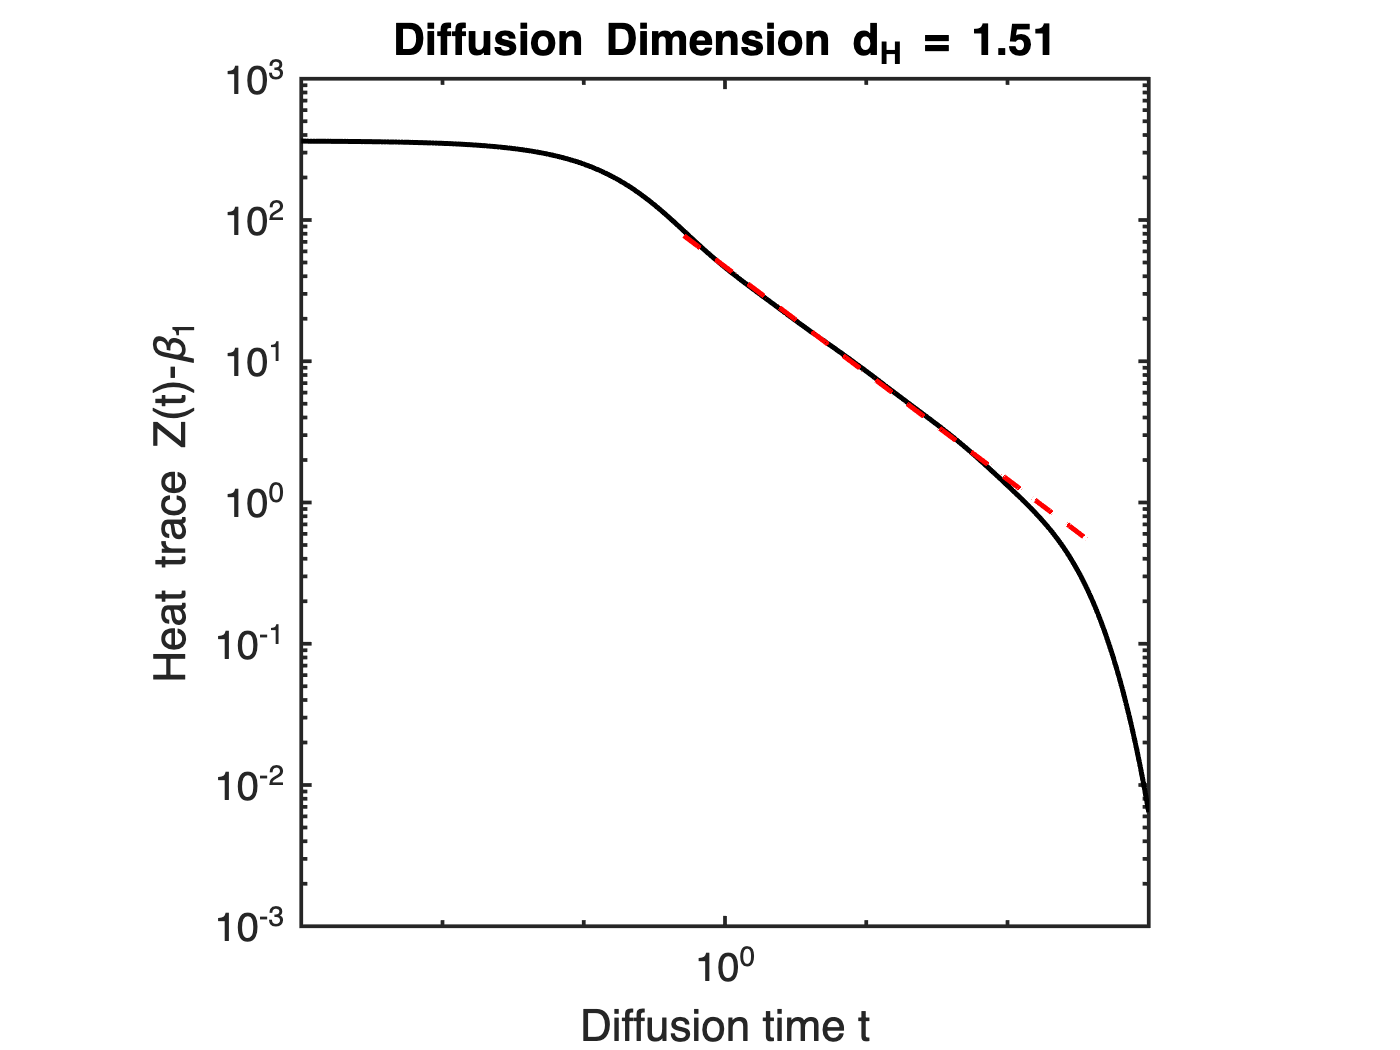

B = PH_boundary(S);
Hodge1 = hodge_laplacian(B,1);
out=hodge_FD(Hodge1,[1 100]); %The interval should be choosen that gives the first desending linear slope.

## Discussion

#### Does flow direction matter?

The proposed diffusion-FD is invariant to arbitrary choices of edge orientation. Edge orientation is needed only to assign signs in the boundary matrices. Suppose the orientation of some edges is reversed. Then boudnary matrices change as


$$B_1 \mapsto B_1D,$$


where $D$ is a diagonal matrix with entries $\pm 1$. For the graph part of the 1-Hodge Laplacian,


$$B_1^\top B_1 \mapsto (B_1D)^\top(B_1D)=D^\top B_1^\top B_1D.$$


Thus, the modified 1-Hodge Laplacian is orthogonally similar to the original Laplacian, and therefore has the same eigenvalues. Thus, heat trace is unchanged by arbitrary edge reorientation. Consequently, the estimated diffusion-FD reflects the intrinsic underlying topology of the network, not the direction of flows. To estimate the intrinsic dimension of the observed flow itself, the metric must be modified to a **Finsler-metric** type that does not impose symmetric costs in opposite directions. The resulting dimension would no longer be a purely structural diffusion dimension; it would be a flow-dependent diffusion dimension that reflects both network topology and directional flow organization.

#### Connection to scale space

The proposed Hodge diffusion scaling can be viewed as a scale-space construction for network data (Lindeberg, 1994). Diffusion time provides the scale parameter. Because each Hodge Laplacian mode decays as $e^{-t\lambda_k}$, this construction is not a direct box-counting generalization of classical FD. Instead, it defines an effective diffusion dimension from the rate at which non-harmonic edge-flow modes attenuate across diffusion scales. Persistent cyclic components are separated through $\beta_1=\dim\ker(\Delta_1)$, while the decaying part $Z(t)-\beta_1$ quantifies multiscale transient interaction complexity. Thus, Hodge diffusion dimension should be interpreted as a coordinate-free spectral analogue of FD for directed edge-flow organization, not as classical Euclidean fractal dimension.

## References

Anand, D.V. and Chung, M.K. [Hodge laplacian of brain networks](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=10005115&casa_token=g_xfXyZkm1QAAAAA:G2MbaFw0K3dlNQtYM_x250ZQMhx407VAn7ygtnoSHwsXzzLMmgzftGa0qQ38P5OcC8NQsmPcVQ&tag=1). *IEEE transactions on medical imaging* 42.5 (2023): 1563-1573.

Barlow, M.T. [Diffusions on fractals](https://personal.math.ubc.ca/~barlow/preprints/stfr.pdf). In *Lectures on Probability Theory and Statistics: Ecole d'Eté de Probabilités de Saint-Flour XXV—1995*, pp. 1-121. Berlin, Heidelberg: Springer Berlin Heidelberg, 2006.

Chung, M.K., Anand, D.V., El-Yaagoubi, A.B., Jung, J.H., Qiu, A. and Ombao, H., 2026. [Causality as a Minimum Energy Principle](https://arxiv.org/pdf/2604.17151). IEEE Engineering in Medicine and Biology Society Annual Conference (EMBC), *arXiv preprint arXiv:2604.17151*.

Das, S., Anand, D. V., & Chung, M. K. (2023). [Topological data analysis of human brain networks through order statistics](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0276419). *Plos one*, *18*(3), e0276419.

Lindeberg, T. [Scale-space theory: A basic tool for analyzing structures at different scales](https://www.tandfonline.com/doi/pdf/10.1080/757582976?casa_token=uYh0XYcSi1kAAAAA:0LlpHaNaoDkBtoVBI5_QNF84vIR00Vws433b8mRg87ozbNeg3wxcVJX_hOSnIeeC6ZhOeipy8Hre). *Journal of applied statistics* 21.1-2 (1994): 225-270.

Rosenberg, S. [The Laplacian on a Riemannian manifold: an introduction to analysis on manifolds](https://www.google.com/books/edition/The_Laplacian_on_a_Riemannian_Manifold/gzJ6Vn0y7XQC?hl=en&gbpv=1&pg=PR5&printsec=frontcover). Cambridge University Press, 1997

Thompson, P.M. [How much data is enough? Uniform convergence bounds for generative & vision-language models under low-dimensional structure](https://arxiv.org/pdf/2512.23109). *arXiv preprint arXiv:2512.23109* (2025).

Thompson, P.M. [How Much Data is Enough? The Zeta Law of Discoverability in Biomedical Data, featuring the enigmatic Riemann zeta function](https://arxiv.org/pdf/2604.17581). *arXiv preprint arXiv:2604.17581* (2026).